# Лабораторная работа 3.6.1

## Спектральный анализ электрических сигналов

Цель работы: изучение спектрального состава переодических элекстрических сигналов.

Оборудование: анализатор спекстра, генератор прямоугльных имплуьсов, генератор сигналов, осциллограф.

## А. Переодическая последовательность прямоугольных импульсов

Коэффициенты при косинусных составляющих в разложении в ряд фурье прямоугольных импульсов с амплитудой $V_0$, длительностью $\tau$, частотой повторения $\Omega_1 =2\frac{\pi }{T}$ равны


$$a_n =2V_0 \frac{\tau }{T}\frac{sin\left(n\cdot \Omega_1 \tau \div 2\right)}{n\cdot \Omega_1 \tau \div 2}$$


Коэффициенты при синуса равны нулю в силу четности. Отсюда следуют соотношения неопределенности


$$\Delta \omega \cdot \tau \approx 2\pi \text{ }или\text{ }\Delta \nu \cdot \tau \approx 1$$


И спектр будет выглядеть так:

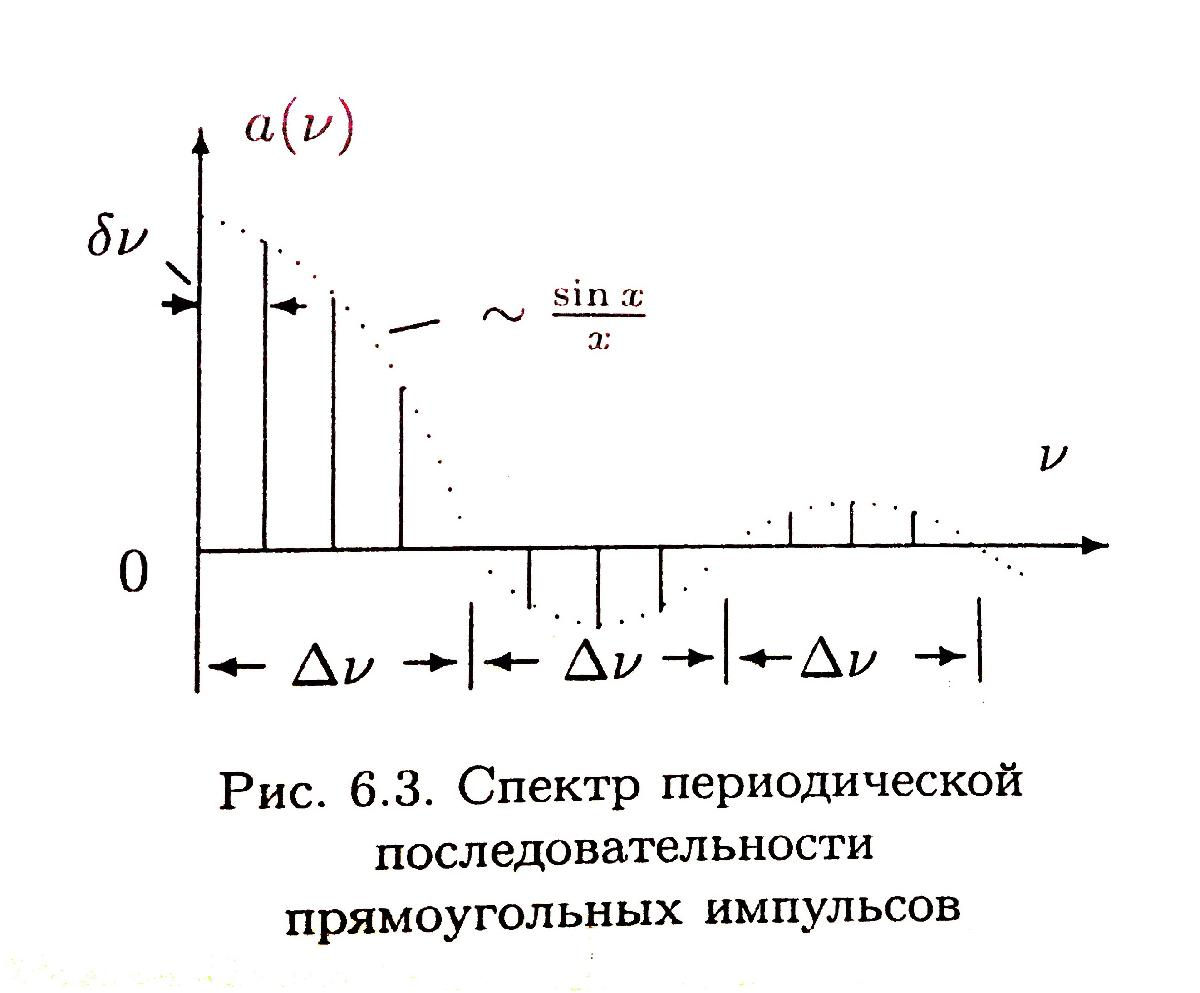

## Б. Переодическая последовательность цугов

Аналогичное выражение для цугов будет


$$a_n =V_0 \frac{\tau }{T}\left(\frac{sin\left\lbrack \left(\omega_0 −n\Omega_1 \right)\frac{\tau }{2}\right\rbrack }{\left(\omega_0 −n\Omega_1 \right)\frac{\tau }{2}}+\frac{sin\left\lbrack \left(\omega_0 +n\Omega_1 \right)\frac{\tau }{2}\right\rbrack }{\left(\omega_0 +n\Omega_1 \right)\frac{\tau }{2}}\right)$$


Тогда, спектр цугов аналогичен спектру прямоугольных импульсов, но сдвинут по частоте, потому соотношения неопределенности сохраняются.

## В. Амплитудно-модулированные колебания.

Пусть гармонические колебания описываются формулой


$$f\left(t\right)=A_0 \left\lbrack 1+m\cdot cos\left(\Omega \cdot t\right)\right\rbrack \cdot cos\left(\omega_0 t\right)$$


причем $\Omega \ll \omega_0$. $m$ - глубина модуляции. Лего видеть, что


$$m=\frac{A_{max} −A_{min} }{A_{max} +A_{min} }$$


А спектр колебаний


$$f\left(t\right)=A_0 \cdot cos\left(\omega_0 t\right)+\frac{A_0 \cdot m}{2}\cdot cos\left(\left(\omega_0 +\Omega \right)t\right)+\frac{A_0 \cdot m}{2}\cdot cos\left(\left(\omega_0 −\Omega \right)t\right)$$


И потому будет выглядеть следующим образом:

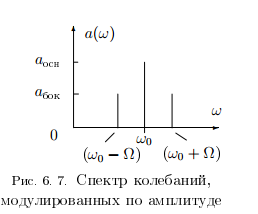

## Ход работы

## А. Исследование спектра переодической последовательности прямоугольных импульсов

- Соберем следующую схему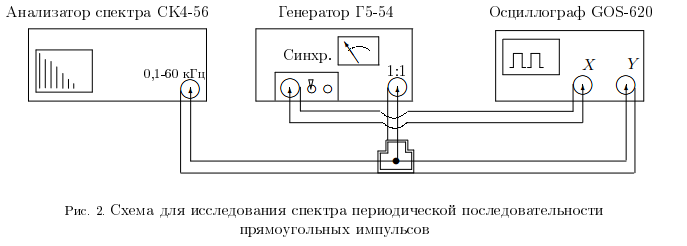

- Получим на экране анализатора спектр импульсов с параметрами $f_{повт} =1\text{ }кГц,\text{ }\tau =25\text{ }мкс,\text{ }m_x =5\text{ }кГц$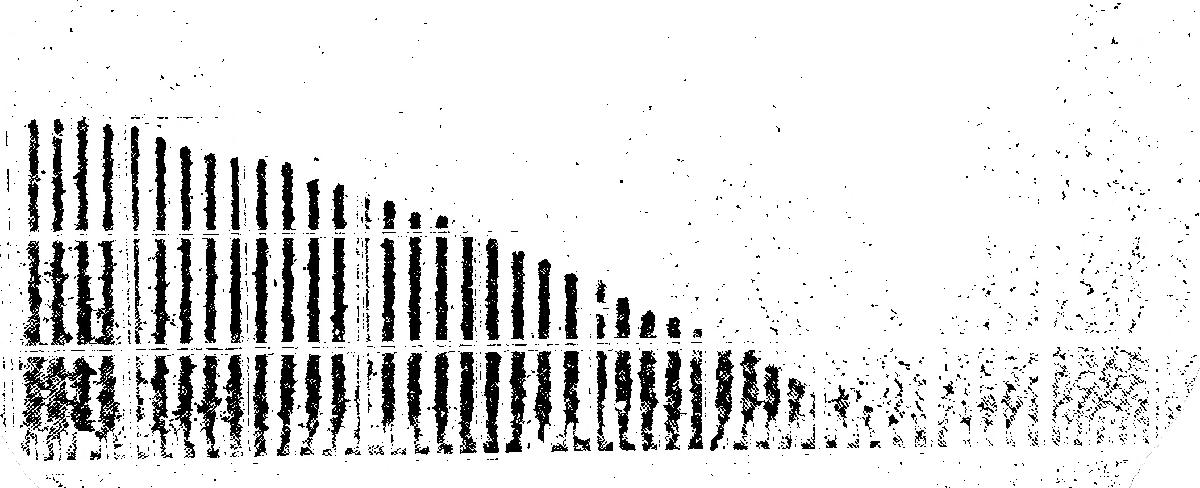

- $f_{\text{повт}} =1\text{ }\text{кГц},\text{ }\tau =50\text{ }\text{мкс},\text{ }m_x =5\text{ }\text{кГц}$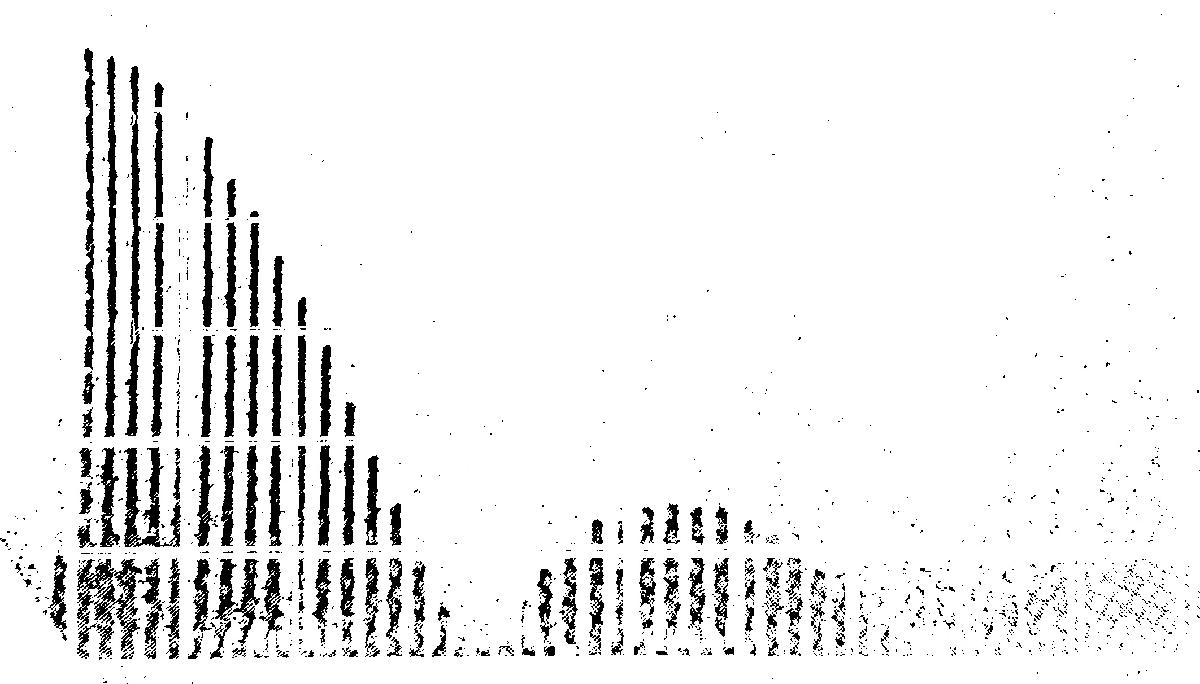

- $f_{\text{повт}} =2\text{ }\text{кГц},\text{ }\tau =25\text{ }\text{мкс},\text{ }m_x =5\text{ }\text{кГц}$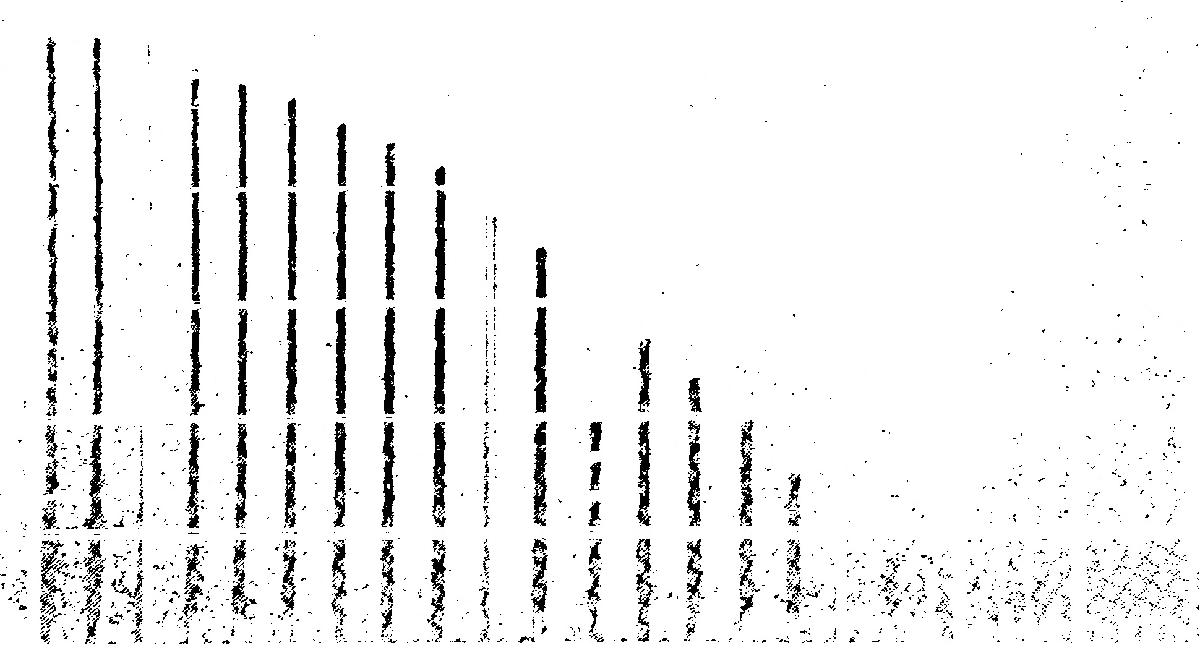

- $f_{\text{повт}} =1\text{ }\text{кГц},\text{ }\tau =100\text{ }\text{мкс},\text{ }m_x =5\text{ }\text{кГц}$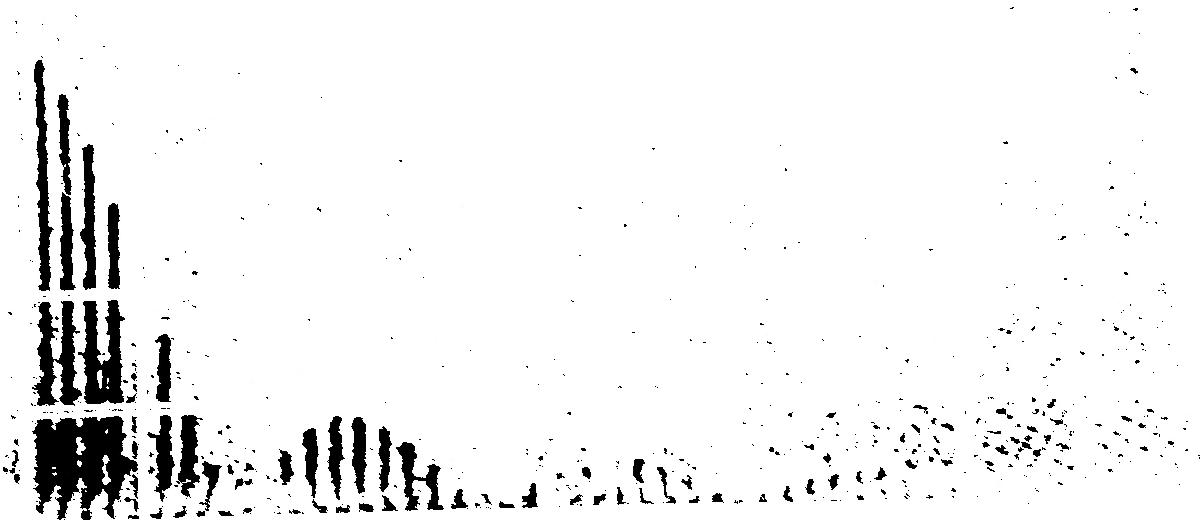

- Снимем зависимость $\Delta \nu \left(\tau \right)$ при $f_{повт} =1\text{ }кГц$ и построим график.

CollectData;
display(dA);

dA =     60    14
    80    12
   100     9
   120     8
   140     6
   160     5
   180     4
   200     4


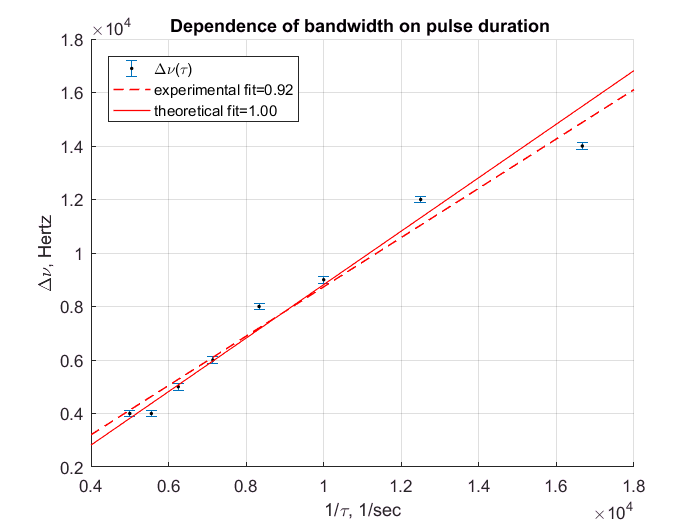

plotA;

## Б. Исследование спектра переодической последовательности цугов гармонических колебаний

- Соберем установку как на схеме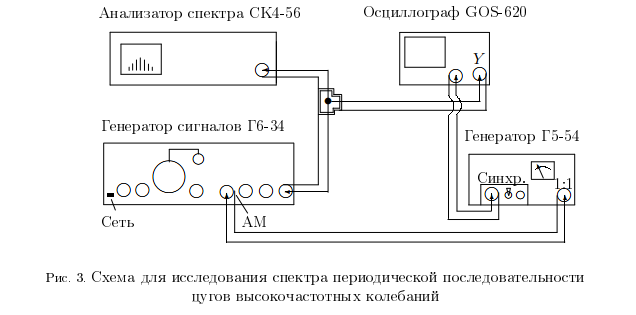

- Получим на экране анализатора спектр цугов с параметрами $\tau =50\text{ }\text{мкс},\text{ }f_{\text{повт}} =1\text{ }\text{кГц},\text{ }\nu_0 =25\text{ }\text{кГц}$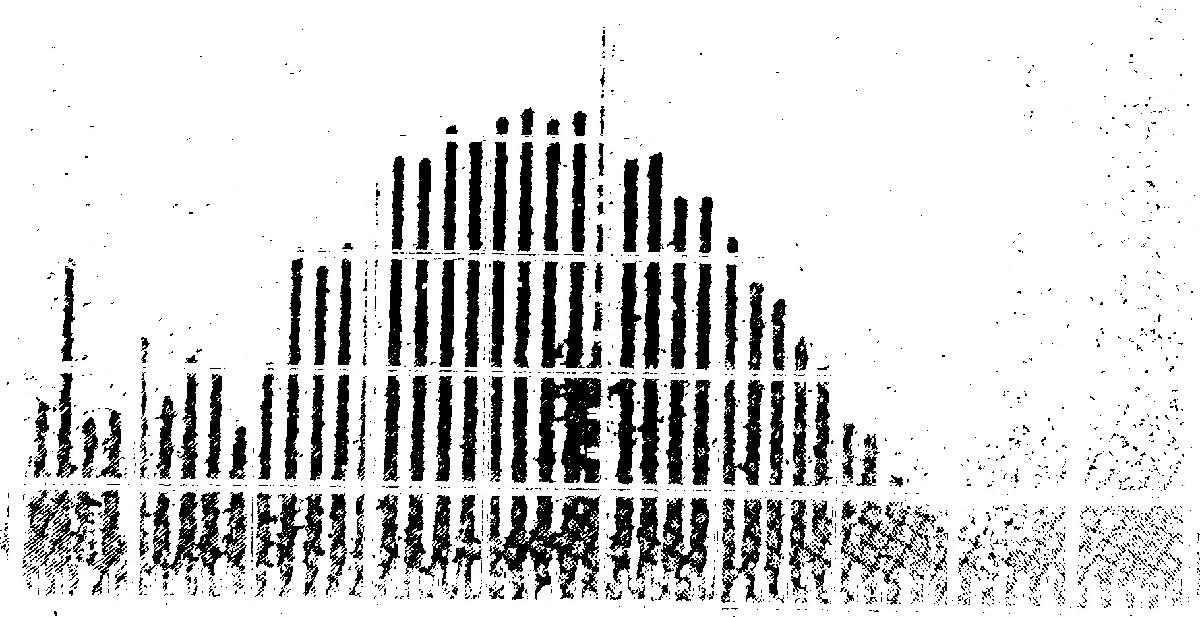

- $\tau =100\text{ }\text{мкс},\text{ }f_{\text{повт}} =1\text{ }\text{кГц},\text{ }\nu_0 =25\text{ }\text{кГц}$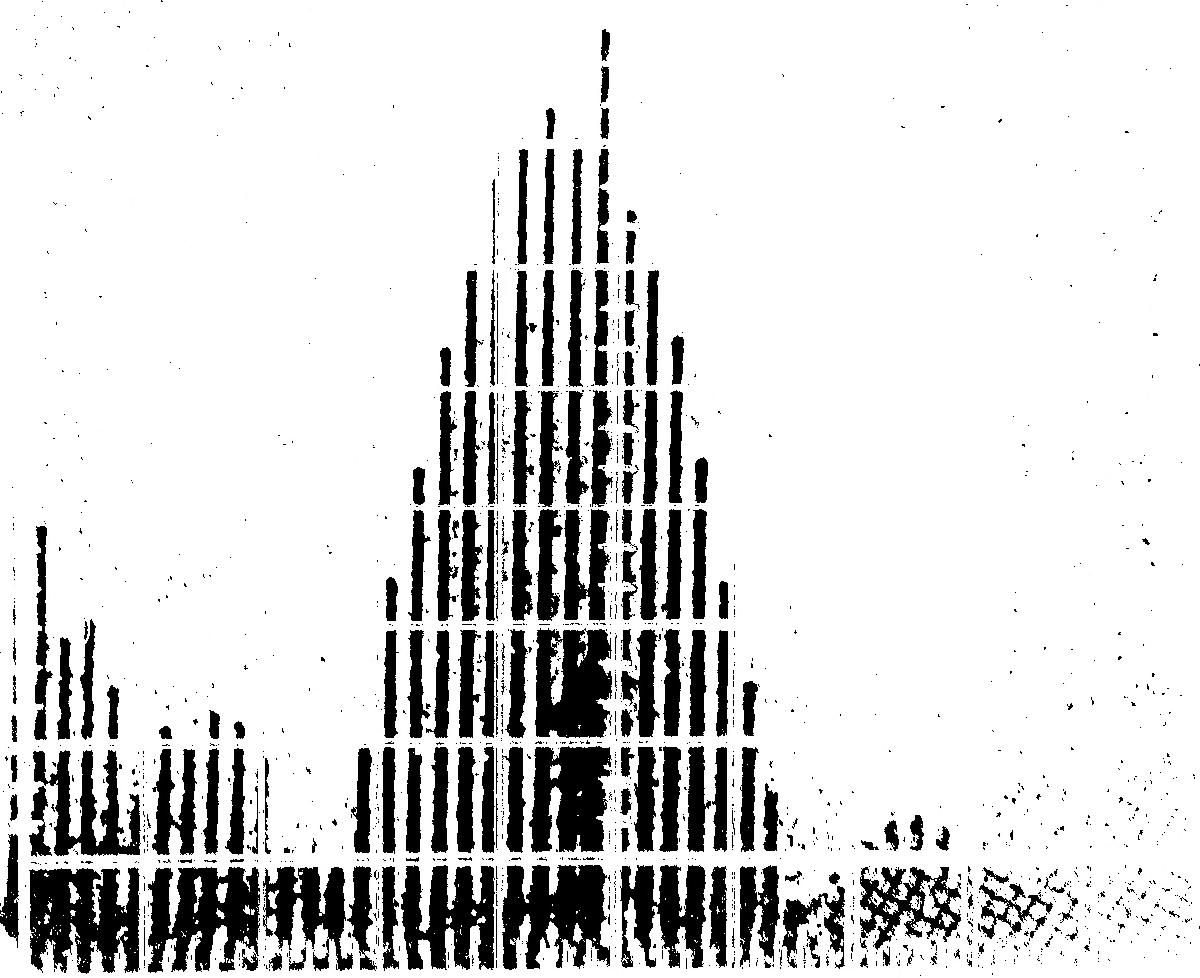

- $\tau =50\text{ }\text{мкс},\text{ }f_{\text{повт}} =1\text{ }\text{кГц},\text{ }\nu_0 =10\text{ }\text{кГц}$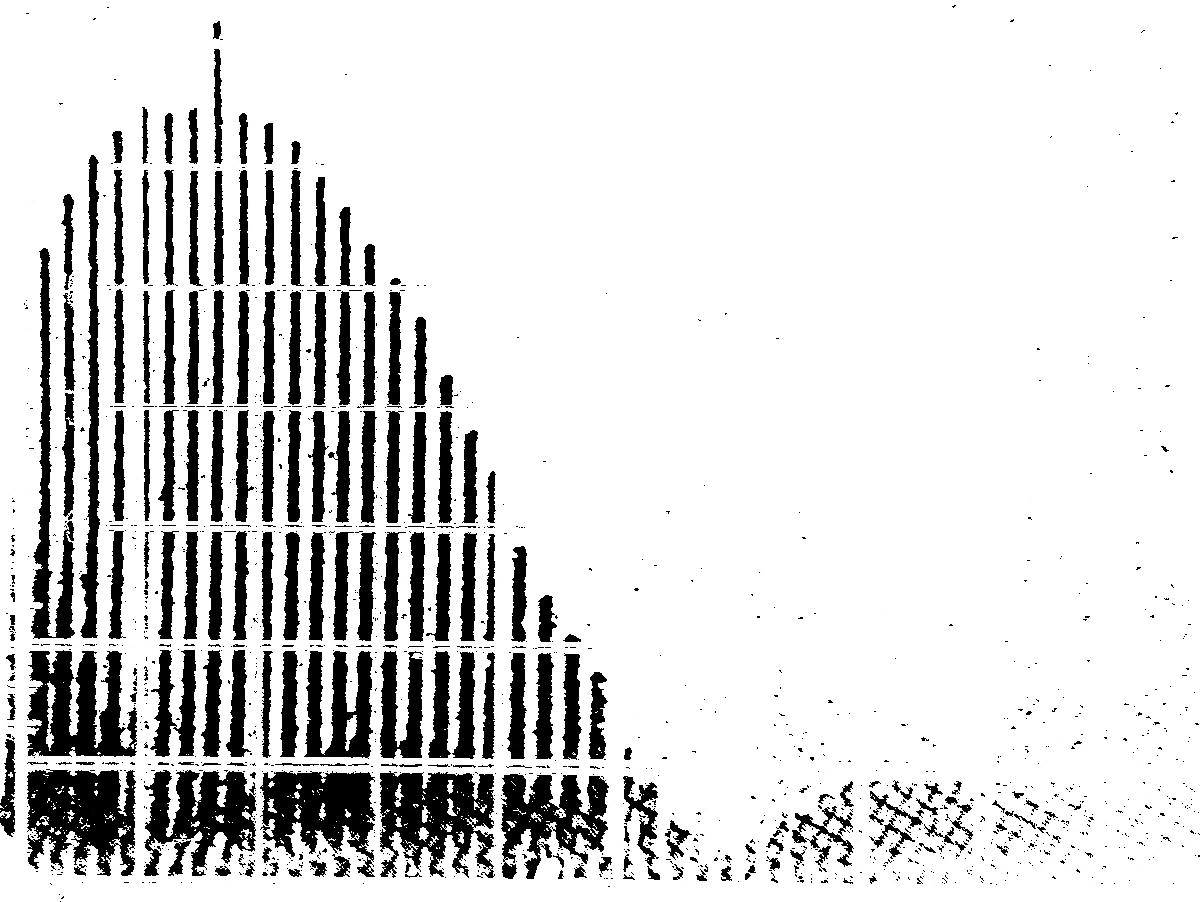

- $\tau =50\text{ }\text{мкс},\text{ }f_{\text{повт}} =1\text{ }\text{кГц},\text{ }\nu_0 =40\text{ }\text{кГц}$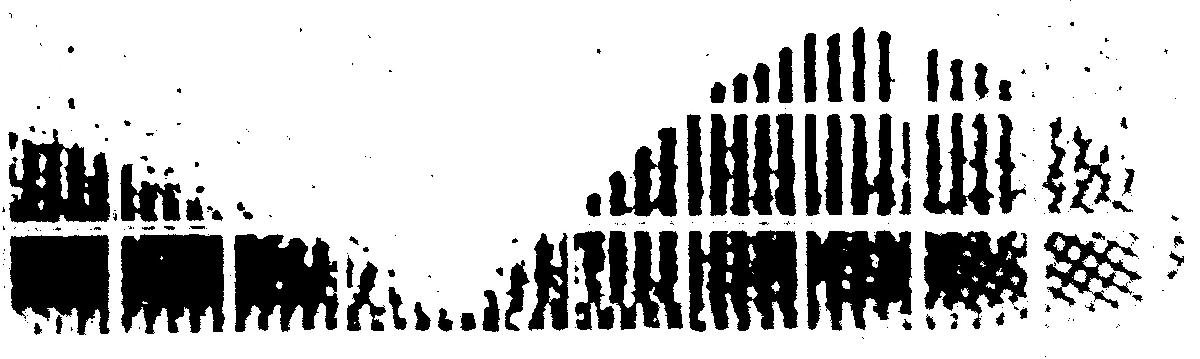

- $\tau =100\text{ }\text{мкс},\text{ }f_{\text{повт}} =2\text{ }\text{кГц},\text{ }\nu_0 =25\text{ }\text{кГц}$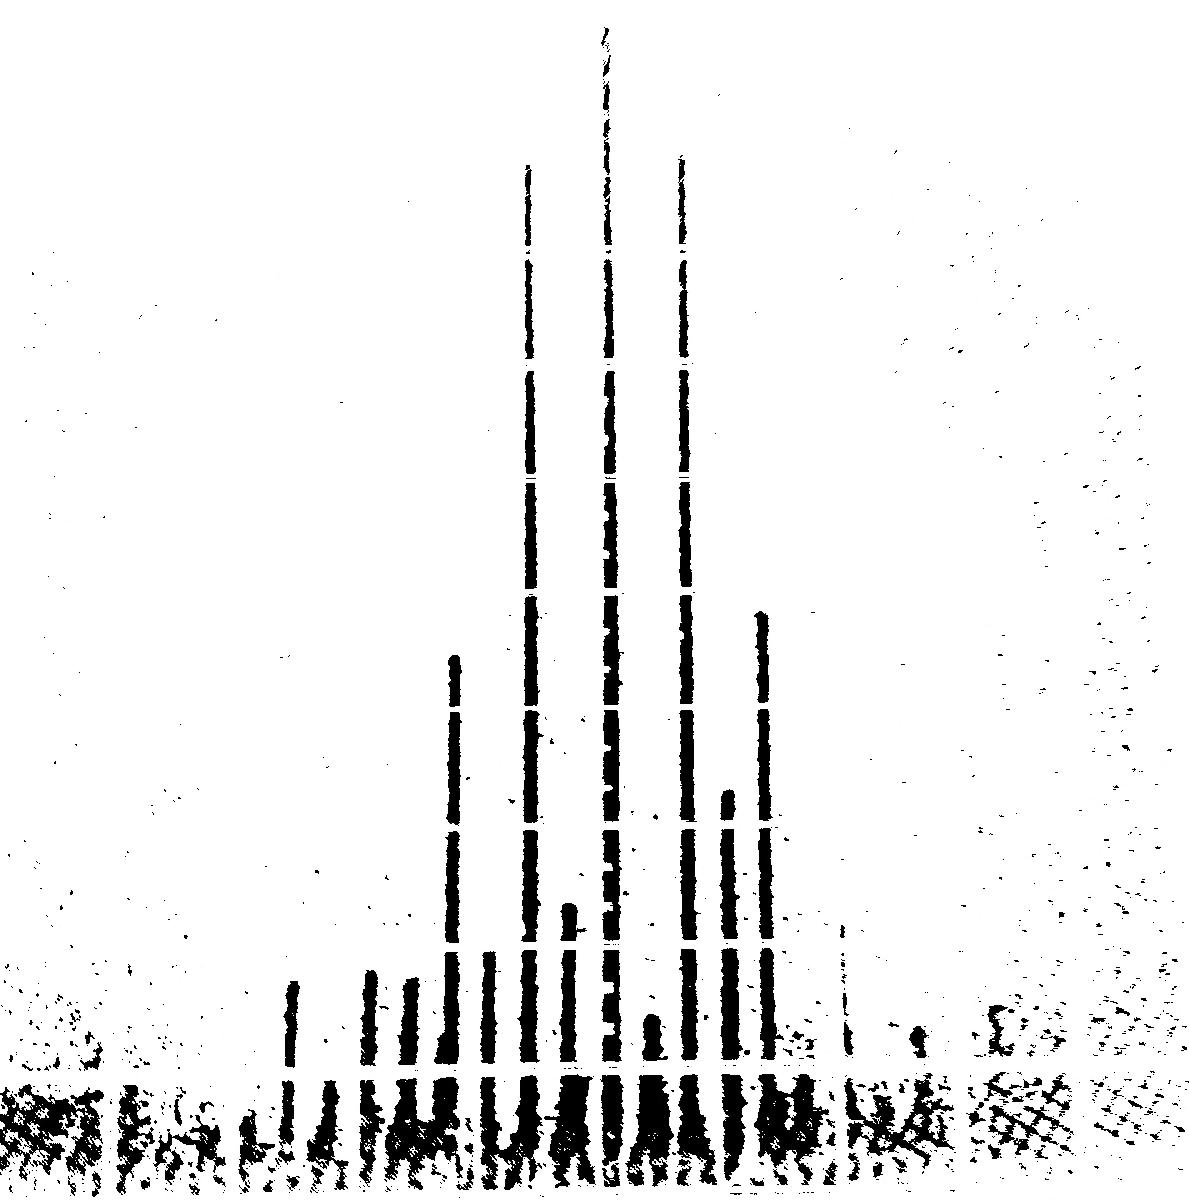

- Снимем зависимость $\delta \nu \left(f_{повт} \right)$ и построим график

disp(dB);

    1.2100    1.0000
    2.2200    2.0000
    3.7000    3.0000
    4.6000    4.0000
    5.9000    5.0000
    7.2000    6.0000
    8.5000    7.0000
    9.5000    8.0000



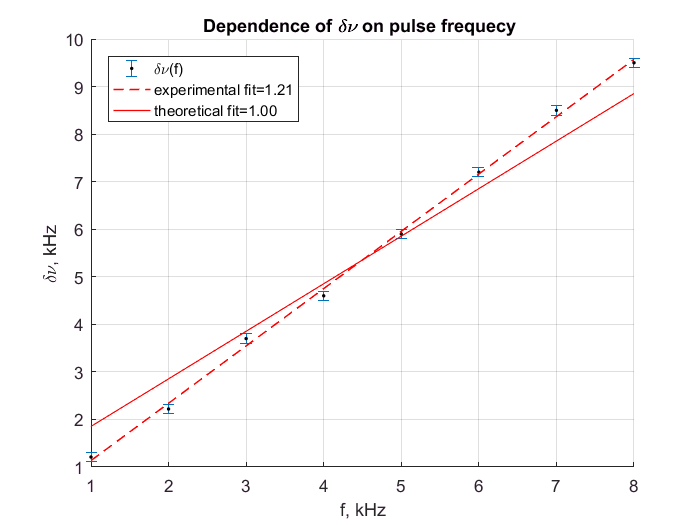

plotB;

## В. Исследование спектра гармонических сигналов, модулированных по амплитуде

- Соберем следующую установку: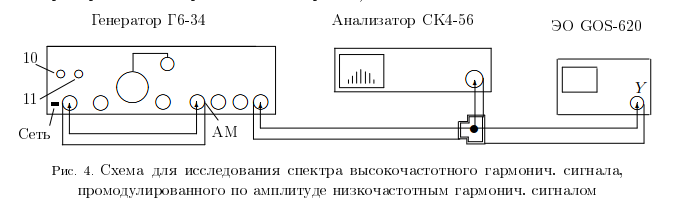

- Снимем зависимость отношения амплитуды боковой линии спектра к амплитуде основной линии от глубины модуляции и построим график.

display([(bigAC-1)./(bigAC+1), 1./littleAC]);

    1.0000    0.5263
    0.9200    0.5000
    0.7701    0.4367
    0.6610    0.3745
    0.5652    0.3448
    0.4595    0.2632



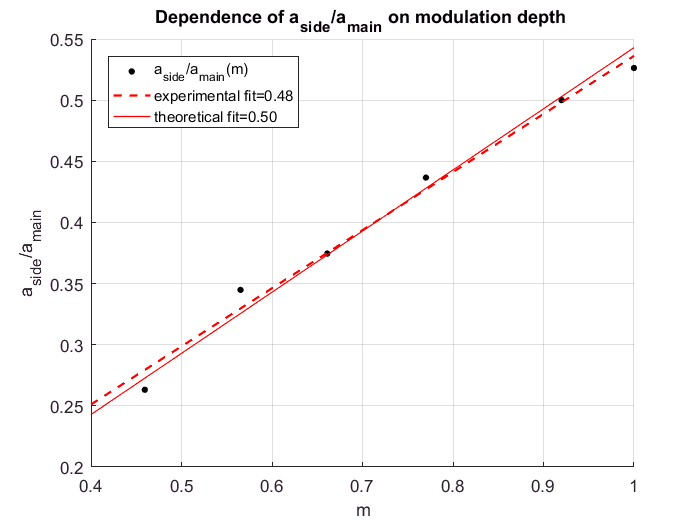

plotC;